# Time evolution for a DAE system on a line with Nuemann boundaries

Evolves the basic heat equation through time.

## Set up the graph structure and coordinates of the problem

By default, the discretization type is uniform but you must choose it to be Chebyshev for the time evolution. You can also set other properties such as the number of discretization points per edge.

L=pi;
nx=32;
Phi = quantumGraph(1,2,L,'nxVec',nx,'RobinCoeff',[0,0],'Discretization','Chebyshev');

## Define the function

1 = heat

2 = linear Schrodinger

3 = KPP

4  = NLS

type = 4;
% funcs = getGraphFcns(Phi.laplacianMatrix,Phi.weightMatrix); f = funcs.f;
f = Phi.myFunc(type);

## Time evolution

You need an initial condition, step size, and how long the program should run till.

xgrid = L*chebptsSecondKind(nx);
[evec,eval] = Phi.eigs(8);
j=3;
lambda = eval(j);
u0 = ; %lambda.*evec(:,j);
tend = .5;
[u,t] = timeEvolveDAEDopri8(Phi,f,u0,1e-4,tend);

## Plotting the solution

Plotting every piece of information is too much. We'll only plot every 100th data point.

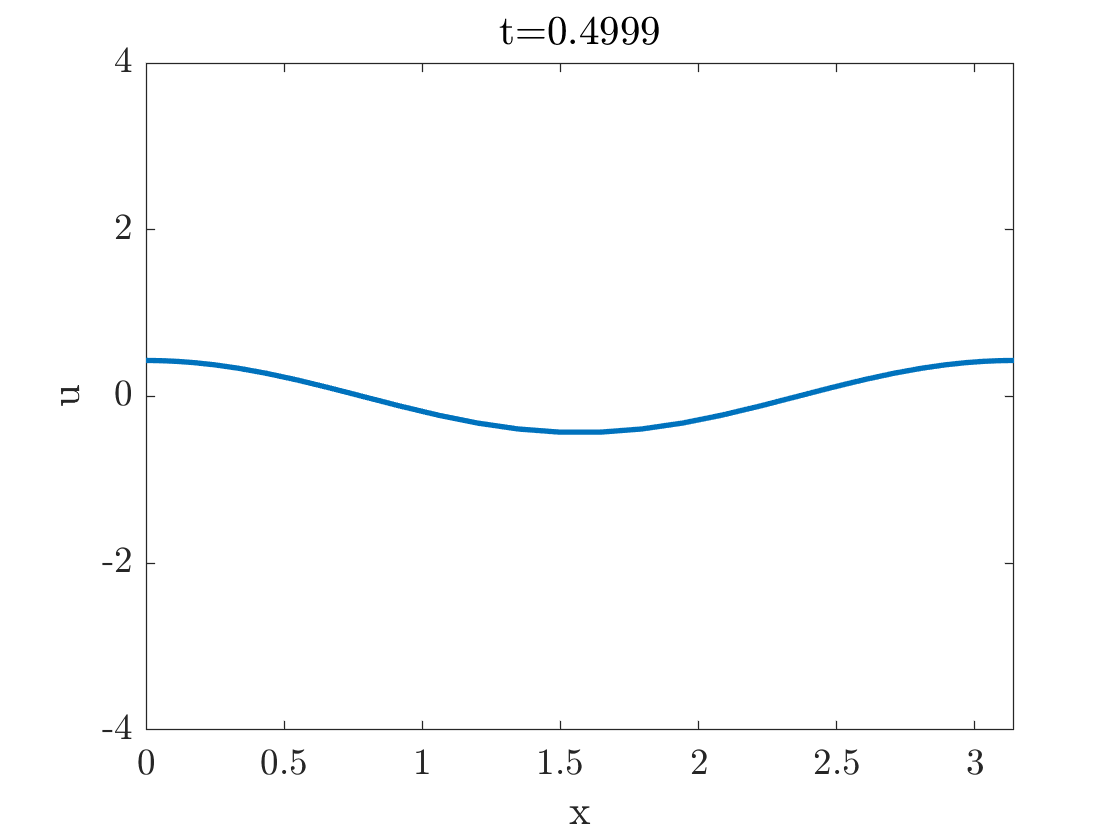

scale = 100;
for i=1:size(u,2)/scale
    clf
    if type == 1
        plot(xgrid,u(:,scale*i))
        axis([0 pi -4 4])
        title(['t=',num2str(t(scale*i))])
        xlabel('x')
        ylabel('u')
    else
        plot(xgrid,abs(u(:,scale*i)).^2)
        axis([0 pi -1 12])
        title(['t=',num2str(t(scale*i))])
        xlabel('x')
        ylabel('u^2')
    end
    pause(.0000000001)
end

## Error Analysis

We use an analytical solution to 

if type == 1
    uana = @(t) exp(-lambda*t).*u0;
else
    uana = @(t) exp(-1i*lambda*t).*u0;
end
error = zeros(1,size(u,2));

for i=1:size(u,2)/scale
    error(scale*i) = max(uana(t(scale*i)) - u(:,scale*i));
end

disp('The error is:')

The error is:


disp(abs(max(error)))

   8.8726e-12

